#                          **Get Trace Statistics of smFRET Data **

%--------------------------------------------------------------------------
%
% lscriptFretTracesStat.mlx:
%   The script is used to evaluate the effectiveness of one or more filters on a 
%   population of traces collected from multiple experiments.
% 
% Description:
%   The script can be used either directly after running scriptGetTraces.m (which creates
%   the fretTraces.mat file) or after running scriptGetTraces.m and scriptFretFilter.m 
%   (which creates the fretTracesPst.mat file).    
% 
% Syntax:  
%   lscriptFretTracesStat
% 
% Inputs:
%   Run the script by using the 'Run and Advance' button.
%   1. Initialize - In code section "User input" of step 1, choose whether to import 
%                   fretTraces.mat (raw data) or fretTracesPst.mat (post-filtered data) 
%                   files.
%
%   2. Step 1     - To import single molecule FRET data into the workspace, the script
%                   prompts the user to select one or more pairs of #Ch1/#Ch2 folders.  
%                   Click CANCEL after selecting all pairs of folders. The script then 
%                   prompts the user to enter a name for the dataset. After that, the 
%                   File Explorer opens again, allowing the user to select a 2nd, 
%                   3rd,... dataset to be imported using the same selection procedure. 
%                   At the end press "CANCEL" and then "NO" to exit Step 1.   
%
%   3. Step 2     - To select a population of traces with certain properties, a 
%                   combination of filters can be applied to the data. The
%                   following filters are available:
%                   a. Intensity 
%                   In the Intensity code section, set the lower (lwLim) and upper 
%                   (upLim) limits of the acceptor and donor intensity filter. All 
%                   traces that have a time-averaged intensity value 'int' in the 
%                   interval Int = {int│lwLim < int < upLim} are selected. The time 
%                   averaging is performed over the range of acceptor or donor track 
%                   time.
%                   b. SNR
%                   The SNR value 's' is time averaged ratio of the acceptor intensity of 
%                   the diffraction limited single molecule spot and its bordering 
%                   background intensity. Time-averaging is performed over the range of 
%                   the acceptor track time. In the SNR code section, set the lower 
%                   (lwLim) and upper (upLim) limits of the acceptor and donor SNR filter.
%                   All traces that have a mean signal to background ratio 's' in the 
%                   interval S = {s │ lwLim < s < upLim } are selected.
%                   c. Crosstalk
%                   Ratio of the time-averaged acceptor intensity of a diffraction-
%                   limited single-molecule spot to its corresponding time-averaged donor 
%                   intensity. Application of this filter primarily removes traces of 
%                   tracked particles with intensities on the order of spectral crosstalk. 
%                   In the Crosstalk code section, set the lower (lwLim) and upper (upLim) 
%                   limits of the 'crt' value. All traces that have a crosstalk value 'crt' 
%                   in the interval Crt = {crt │ lwLim < crt <upLim } are selected.  
%                   d. trace length
%                   In the Trace length code section, set the lower (lwLim) and upper 
%                   (upLim) limits for the acceptor trace length in frames. All traces with 
%                   a trace length 'lt' in the time interval LT = { lt │ lwLim < lt < upLim } 
%                   are selected.
%                   NOTE: 
%                   All selected filters are linked with AND logic, which means that a trace
%                   must pass all filter criteria to be accepted.
%
%                   Running this step opens the file explorer and prompts the user to enter  
%                   a filename for the structure variable cellData. 
%
%   4. Step 3     - Step 3 is optional. It allows the user to readjust the filters described 
%                   in Step 2 and apply them again to the same data set. Performing this 
%                   step allows to compare the trace populations acquired with different 
%                   filter settings. Running this step opens the file explorer and prompts 
%                   the user to enter a new filename for the structure variable cellData.
% Outputs:
%   1. Step 1     - The selected path and the names of the imported folders are displayed 
%                   for each dataset in the output window.  
%
%   2. Step 2     - a) Summary table for each uploaded dataset. The table has the following
%                   column titles:
%                   - cellNo : An integer number that identifies a particular experiment.
%                   - Symbol: Each dataset in a diagram has its own marker symbol. 
%                   - nAcc : An integer indicating the number of acceptor spots detected. 
%                   - nTraces: An integer indicating the number of traces detected by the 
%                     particle tracker.   
%                   - nPstFlt: An integer indicating the number of traces after applying a 
%                     combination of trace filters. 
%                   - diffPrePost: Difference between nTraces and nPstFlt.
%                   - pctPrePst: Percentage of traces discarded by the combination of filters.
%                   b) A 2x4 panel with the following diagrams:
%                   Top row from left to right:
%                   - Trace length in frames as a function of mean acceptor intensity.
%                   - Trace length in frames as a function of mean donor intensity.
%                   - Trace length in frames as a function of mean crosstalk value.
%                   - Trace length in frames as a function of mean acceptor... 
%                     signal-to-background ratio. 
%                   Bottom row from left to right:
%                   - Mean acceptor signal-to-background ratio as a function of mean acceptor
%                     intensity.
%                   - mean donor signal-to-background ratio as a function of mean donor 
%                     intensity.
%                   - mean crosstalk value as a function of mean acceptor intensity.
%                   - mean crosstalk value as a function of mean donor intensity. 
%                   c) A structure variable cellData is saved in a folder specified by the 
%                   user (see readFretDatasets.m function for a full description of the 
%                   cellData variable).
%
%  3. Step 3        The same output as in step 2.  A new structure variable cellData is saved 
%                   in a folder specified by the user (see readFretDatasets.m function for a 
%                   full description of the cellData variable). 
%
% Other m-files required: 
%   Subfunctions: readFretDatasets.m, colorSelection.m, markerSelection.m
%
% See also: 
%   scriptGetFretTraces.m, scriptFretFilter.m
%
% Authors: 
%   - P.G.
%
% Copyright:
%    2011-2020 Columbia Univiversity / RFMH All Rights Reserved.
%
% -------------------------------------------------------------------------

# Step 1: Load Single Molecule FRET Data 

- **User-input in code section USER INPUT: Choose to import a fretTraces.mat or a fretTracesPst.mat file**

- **Select multiple directories (always select:     #...Ch01 AND   #...Ch02     DIRECTORIES) **

%% Load FRET Data
clc;
% Initialize Variables
clear;
z = 0;
legendName  = cell(1,1);
combDataSets = cell(1,1);

% Load Data Sets
while 1
    z = z+1;
    disp(['dataset: ' num2str(z)]);
    % Run function to load data
    % ----------------- USER INPUT -------------------
    % dataSet_j = readFretDatasets('fretTraces.mat');
    dataSet_j = readFretDatasets('fretTracesPst.mat');
    % ------------------------------------------------
    if isempty(dataSet_j)
        choice = questdlg('Continue ?',' no fretData selected...','YES','NO','NO');
        switch choice
            case 'YES'
                continue
            case 'NO'
                break
        end
    else
        % Save Data
        combDataSets{1,z} = dataSet_j;
        % Input Legend Name
        prompt = {'Enter Legend Name:'};
        dlg_title = ['Legend ' num2str(z)];
        num_lines = 1;
        defaultans = {['data' num2str(z)];};
        legendName{z} = inputdlg(prompt,dlg_title,num_lines,defaultans);
    end
end

dataset: 1


F:\Disk E\#BackupMicData\2017 May-Jun\170511_WA-MH_SNAPf-mGlu2-Cy3AC-Cy5AC_w&wo Glu_Live FRET\333 nM Cy3AC_666 nM Cy5AC_PassX_100 ngmL tet_50 PCA PCD\Track_Opt28-TW5_52418\LT20FreeNoCrt
   
#01Ch1#02Ch1
#01Ch2#02Ch2


dataset: 2


F:\Disk E\#BackupMicData\2017 May-Jun\170511_WA-MH_SNAPf-mGlu2-Cy3AC-Cy5AC_w&wo Glu_Live FRET\333 nM Cy3AC_666 nM Cy5AC_PassX_100 ngmL tet_50 PCA PCD\Track_Opt28-TW5_52418\LT20FreeNoCrt
   
#03Ch1
#03Ch2


dataset: 3



% Delete empty cells
idxIsEmpty   = cellfun('isempty',combDataSets); 
combDataSets = combDataSets(~idxIsEmpty);
legendName   = legendName(~idxIsEmpty); 

# Step 2: Apply Filter to Data

- **User Input: Set Fliter Values (line 48 to 61)**

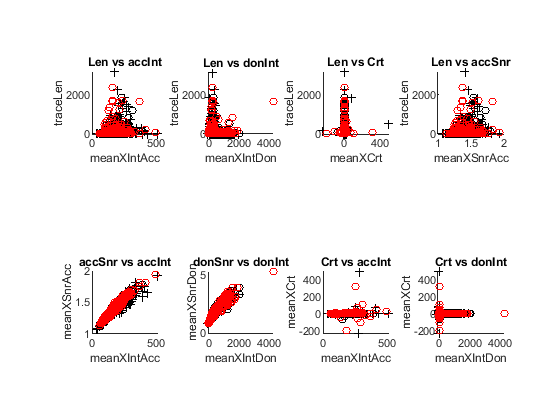

data1: Black
    cellNo    Symbol    nAcc    nTraces    nPostFlt    diffPrePst    pctPrePst
    ______    ______    ____    _______    ________    __________    _________

       1      'o 30'     85      1650         321         1329         0.81   
       2      '+ 30'    264      3211         733         2478         0.77   
     NaN      'NaN'     349      4861        1054         3807         0.78   

-------


data2: Red
    cellNo    Symbol    nAcc    nTraces    nPostFlt    diffPrePst    pctPrePst
    ______    ______    ____    _______    ________    __________    _________

       3      'o 30'    212      3031        606          2425          0.8   
     NaN      'NaN'     212      3031        606          2425          0.8   

-------


%---Plot new figure for every data set (yes = 1 / no = 0) 
flagNewFig = 0;
figure;

% Density Data
densityVar = {'nDon','nAcc'}; 
densityData = densityVar{2}; %input 1 = nDon or 2 = nAcc

%---Intensity 
lwLim_meanXIntAcc = -inf;
upLim_meanXIntAcc = inf;
lwLim_meanXIntDon = -inf;
upLim_meanXIntDon = inf;

%---SNR
lwLim_meanXSnrAcc = -inf;
upLim_meanXSnrAcc = inf;
lwLim_meanXSnrDon = -inf;
upLim_meanXSnrDon = inf;

%---Crosstalk
lwLim_meanXCrt = -inf;
upLim_meanXCrt = inf;

%---Trace length 
lwLim_traceLen = 0;
upLim_traceLen = 4001;

%---Initialize Variables
nPlots      = 8;
nDataSets   = size(combDataSets,2);
xl          = zeros(nPlots,2,nDataSets);
yl          = zeros(nPlots,2,nDataSets);
statDataPst1 = cell(nDataSets,2);
cellData=[];
%---Data processing 
for i=1:nDataSets
    
    %---Load Data and Delete empty rows
    cellData1       = combDataSets{1,i};
    
    %---Callback filter function
    cellDataTmp = filterDataSets(cellData1,...
                                 lwLim_meanXIntAcc,upLim_meanXIntAcc,...
                                 lwLim_meanXIntDon,upLim_meanXIntDon,...
                                 lwLim_meanXSnrAcc,upLim_meanXSnrAcc,...
                                 lwLim_meanXSnrDon,upLim_meanXSnrDon,...
                                 lwLim_meanXCrt,upLim_meanXCrt,...
                                 lwLim_traceLen,upLim_traceLen);
                             
    cellData  = [cellData,cellDataTmp]; %#ok<AGROW>   
                                 
    %---Plot panel
    [color,colorName] = colorSelection(i);
    plotPanel(cellDataTmp,legendName{i}{1},flagNewFig,color);
    
    % Save axes limits of the n plots 
    for j=1:nPlots
        subplot(2,4,j); xl(j,:,i) = xlim; yl(j,:,i) = ylim; 
    end
    
    %---PLot Table
    tmpStat = plotTable(cellDataTmp, legendName{i}{1},colorName,densityData);
    statDataPst1{i,1} = tmpStat{1,1};
    statDataPst1{i,2} = tmpStat{1,2};
    
end


% Save cellData data
[file,path] = uiputfile('cellDataPst1.mat','Save file name');
if file > 0
    save([path filesep file],'cellData');
end


# Step 3: Apply Filter to Data (for comparison)  

- **User Input: Set Fliter Values (line 120 to 133)**

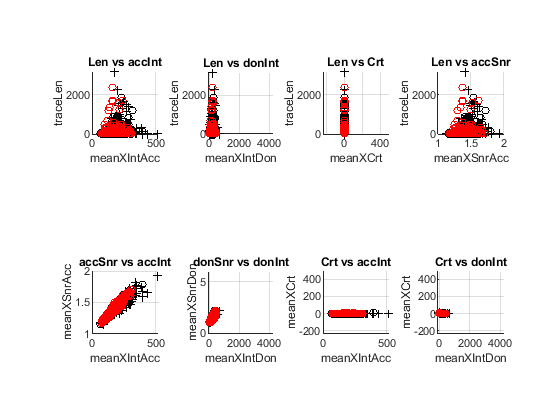

data1: Black
    cellNo    Symbol    nAcc    nTraces    nPostFlt    diffPrePst    pctPrePst
    ______    ______    ____    _______    ________    __________    _________

       1      'o 30'     85      1650        271          1379         0.84   
       2      '+ 30'    264      3211        577          2634         0.82   
     NaN      'NaN'     349      4861        848          4013         0.83   

-------


data2: Red
    cellNo    Symbol    nAcc    nTraces    nPostFlt    diffPrePst    pctPrePst
    ______    ______    ____    _______    ________    __________    _________

       3      'o 30'    212      3031        443          2588         0.85   
     NaN      'NaN'     212      3031        443          2588         0.85   

-------


%%---Set Limits

%---Plot new figure for every data set (yes = 1 / no = 0) 
flagNewFig = 0;
figure;

%---Intensity 
lwLim_meanXIntAcc = -inf;
upLim_meanXIntAcc = inf;
lwLim_meanXIntDon = -inf;
upLim_meanXIntDon = inf;

%---SNR
lwLim_meanXSnrAcc = -inf;
upLim_meanXSnrAcc = +inf;
lwLim_meanXSnrDon = -inf;
upLim_meanXSnrDon = +inf;

%---Crosstalk
lwLim_meanXCrt = 0.4;
upLim_meanXCrt = 10;

%---Trace length 
lwLim_traceLen = 0;
upLim_traceLen = 4001;

%---Data processing 
statDataPst2 = cell(nDataSets,2);
cellData=[];
for i=1:nDataSets
    
    %---Load Data and Delete empty rows
    cellData2       = combDataSets{1,i};
 
    %---Callback filter function
    cellDataTmp = filterDataSets(cellData2,...
                                 lwLim_meanXIntAcc,upLim_meanXIntAcc,...
                                 lwLim_meanXIntDon,upLim_meanXIntDon,...
                                 lwLim_meanXSnrAcc,upLim_meanXSnrAcc,...
                                 lwLim_meanXSnrDon,upLim_meanXSnrDon,...
                                 lwLim_meanXCrt,upLim_meanXCrt,...
                                 lwLim_traceLen,upLim_traceLen);
    
    cellData  = [cellData,cellDataTmp];  %#ok<AGROW>                     
                     
    %---Plot panel of filtered Fret data
    [color,colorName] = colorSelection(i);
    plotPanel(cellDataTmp,legendName{i}{1},flagNewFig,color);

    % Use saved axes limits and resize axis
    for j=1:nPlots
        subplot(2,4,j);
        xlim(xl(j,:,i)); ylim(yl(j,:,i)); 
        grid on;
    end
    
    %---Plot Table
    tmpStat = plotTable(cellDataTmp, legendName{i}{1} ,colorName,densityData);
    statDataPst2{i,1} = tmpStat{1,1};
    statDataPst2{i,2} = tmpStat{1,2};
    
end


% Save cellData data
[file,path] = uiputfile('cellDataPst2.mat','Save file name');
if file > 0
    save([path filesep file],'cellData');
end


# Callback Functions

## Callback Function: Filter Data Sets 

function [celldataflt]=filterDataSets(celldata,...
                                      lwLim_meanXIntAcc,upLim_meanXIntAcc,...
                                      lwLim_meanXIntDon,upLim_meanXIntDon,...
                                      lwLim_meanXSnrAcc,upLim_meanXSnrAcc,...
                                      lwLim_meanXSnrDon,upLim_meanXSnrDon,...
                                      lwLim_meanXCrt,upLim_meanXCrt,...
                                      lwLim_traceLen,upLim_traceLen)
% Apply the limits and Plot new Panel
nCells = size(celldata,2);
celldataflt = struct('path',[],...
                     'acc',[],...
                     'don',[],...
                     'nTraces',[],...
                     'nPstFlt',[],...
                     'traceMetadata',[],...
                     'density',[]);
    for j=1:nCells
        % Load tmp dataset
        
        combfret_j = celldata(j).traceMetadata;
        if ~isempty(combfret_j)
            % Filter definition 
            fltXIntAcc = ([combfret_j.meanXIntAcc] > lwLim_meanXIntAcc &...
                          [combfret_j.meanXIntAcc] < upLim_meanXIntAcc)';
            fltXIntDon = ([combfret_j.meanXIntDon] > lwLim_meanXIntDon &...
                          [combfret_j.meanXIntDon] < upLim_meanXIntDon)';
            fltXSnrAcc = ([combfret_j.meanXSnrAcc] > lwLim_meanXSnrAcc &...
                          [combfret_j.meanXSnrAcc] < upLim_meanXSnrAcc)';
            fltXSnrDon = ([combfret_j.meanXSnrDon] > lwLim_meanXSnrDon &...
                          [combfret_j.meanXSnrDon] < upLim_meanXSnrDon)';
            fltXCrt    = ([combfret_j.meanXCrt]    > lwLim_meanXCrt &...
                          [combfret_j.meanXCrt]    < upLim_meanXCrt)';
            fltTrLen   = ([combfret_j.traceLen]    > lwLim_traceLen &...
                          [combfret_j.traceLen]    < upLim_traceLen)';
            % Apply all filters
            flt        = fltXIntAcc &...
                         fltXIntDon &...
                         fltXSnrAcc &...
                         fltXSnrDon &...
                         fltXCrt &...
                         fltTrLen;
            
            celldataflt(j).traceMetadata = combfret_j(flt);
            celldataflt(j).nPstFlt    = size(celldataflt(j).traceMetadata,2);
        else
            celldataflt(j).nPstFlt    = 0;
        end
        celldataflt(j).path        = celldata(j).path;
        celldataflt(j).acc         = celldata(j).acc;
        celldataflt(j).don         = celldata(j).don;
        celldataflt(j).nTraces     = celldata(j).nTraces;
        
        celldataflt(j).density     = celldata(j).density;
    end
end


## Callback Function: Plot Panels 

function [] = plotPanel(celldata,legendName,flagNewFig,color)
% Plot Panel with 5 Combinations of fret data 
    nCells = size(celldata,2);
    if ~isempty([celldata.traceMetadata])
        
        if flagNewFig ==1,figure,end 
        
        ax         = {'ax1','ax2','ax3','ax4',...
                      'ax5','ax6','ax7','ax8'};
                                
        YY         = {'traceLen',    'traceLen',    'traceLen', 'traceLen',...
                      'meanXSnrAcc', 'meanXSnrDon', 'meanXCrt','meanXCrt' };
                  
        XX         = {'meanXIntAcc', 'meanXIntDon', 'meanXCrt','meanXSnrAcc',  ...
                      'meanXIntAcc', 'meanXIntDon', 'meanXIntAcc','meanXIntDon'};
                  
        titleNames = {'Len vs accInt','Len vs donInt','Len vs Crt','Len vs accSnr',...
                      'accSnr vs accInt', 'donSnr vs donInt','Crt vs accInt','Crt vs donInt'};

        % Plot N graphs in a figure panel
        N = numel(XX);
        for i=1:N
            % Plot nDataSets in Graph i each with a different color
            ax{i} = subplot(2,4,i);
            for j=1:nCells
                % Select Symbol
                [markerType,markerSize] = markerSelection(j);
                % Load tmp dataset 
                CombFret_j = celldata(j).traceMetadata;
                % Generate scatter plots
                if ~isempty(CombFret_j)
                    scatter([CombFret_j.(XX{i})],[CombFret_j.(YY{i})],...
                             markerSize,...
                             markerType,...
                             'MarkerEdgeColor', color);
                    hold(ax{i},'on');
                end
            end
            % Label Axes
            title(ax{i},titleNames{i});
            xlabel(ax{i},XX{i})
            ylabel(ax{i},YY{i})
            % Plot legend
            if i==1 && flagNewFig ==1 
                legend(legendName);
            else
                legend('off');
            end
        set(ax{i},'PlotBoxAspectRatio',[1 0.95 0.95]);
        end
    else
        warning('no Data available');
    end
end


## Callback Function: Table

function statData = plotTable(celldata,legendname,colorname,densityData)
    statData = cell(1,2);
        nCells         = size(celldata,2);
        cellNo         = zeros(nCells+1,1);
        nTraces        = zeros(nCells+1,1);
        %nPreFlt  = zeros(nCells+1,1);
        nPstFlt        = zeros(nCells+1,1);
        diffPrePost    = zeros(nCells+1,1);
        pctPrePost     = zeros(nCells+1,1);
        nSpots         = zeros(nCells+1,1);
        %normTraces     = cell(nCells+1,1);
        %normPreFlt     = cell(nCells+1,1);
        %normPostFlt     = cell(nCells+1,1);
        markerSymbol   = cell(nCells+1,1);
        for j=1:nCells
            
            txt        = celldata(j).acc;
            cellNoStr  = textscan(txt(2:3),'%2c');
            cellNo(j)  = str2double(cellNoStr{1});
            
            [markerType,markerSize] = markerSelection(j);
            
            markerSymbol{j}   = [markerType ' ' num2str(markerSize)];
            switch densityData
                case 'nDon'
                    if ~isempty(celldata(j).density) 
                        nSpots(j)      = celldata(j).density(1);
                    end
                case 'nAcc'
                    if ~isempty(celldata(j).density) 
                        nSpots(j) = celldata(j).density(4);
                    end
            end
            
            nTraces(j)        = celldata(j).nTraces;
            %tmp=round(nTraces(j)/nSpots(j),1);
            %normTraces{j}     = [num2str(nTraces(j)) ' ' num2str(tmp)];
            %normTraces{j}     = num2str(nTraces(j));
            
            nPstFlt(j) = celldata(j).nPstFlt;
            %tmp=round(nPstFlt(j)/nSpots(j),2);
            %normPostFlt{j}    = [num2str(nPstFlt(j)) ' ' num2str(tmp)];
            
            diffPrePost(j)    = nTraces(j) - nPstFlt(j);
            pctPrePost(j)     = (nTraces(j) - nPstFlt(j))/nTraces(j);
            
        end
        
        % Include Column Sum
        cellNo(j+1)         = NaN;
        markerSymbol{j+1}   = 'NaN';
        nTraces(j+1)        = sum(nTraces(1:end-1)); 
        nPstFlt(j+1)        = sum(nPstFlt(1:end-1));
        diffPrePost(j+1)    = sum(diffPrePost(1:end-1));
        pctPrePost(j+1)     = (nTraces(j+1) - nPstFlt(j+1))/nTraces(j+1);
        nSpots(j+1)      = sum(nSpots(1:end-1));
        %tmp = round(nTraces(j+1)/nSpots(j+1),1);
        %normTraces{j+1}     = [num2str(nTraces(j+1)) '   ' num2str(tmp)];
        %tmp = round(nPstFlt(j+1)/nSpots(j+1),2);
        %normPostFlt{j+1}    = [num2str(nPstFlt(j+1)) '   ' num2str(tmp)];
                  
        
        T = table(cellNo,...
                  markerSymbol,...
                  nSpots,... 
                  nTraces,...
                  nPstFlt,...
                  diffPrePost,...
                  round(pctPrePost,2,'significant'));
        T.Properties.VariableNames = {'cellNo',...
                                      'Symbol',...
                                       densityData,...
                                      'nTraces',...
                                      'nPostFlt',...
                                      'diffPrePst',...
                                      'pctPrePst'};
        statData{1,1} = legendname;
        statData{1,2} = T;
        disp([legendname ': ' colorname]);disp(T);
        disp('-------');
end